%% ELEC5305 – Traditional vs Segment-wise Instrument Classification
% 比较：
%  1) 传统：直接用预提取特征 Xtest 做一次性预测
%  2) 新方法：从原始音频分段提特征 + 投票（与 demo 一致）
%
% 只依赖：
%   results/ml/philharmonia_features.mat   (X, Labels, Names, fsRef)
%   data/philharmonia/audio/*.wav         (原始 Philharmonia 音频)

clear; clc;

%% === 0. 自动定位 projectRoot，确保老师电脑也能复现 ===
try
    thisFile = matlab.desktop.editor.getActiveFilename;
catch
    thisFile = '';
end
if ~isempty(thisFile)
    here = fileparts(thisFile);
else
    here = pwd;
end

% 向上找，直到找到 philharmonia_features.mat
root = here;
featRel = fullfile('results','ml','philharmonia_features.mat');
for k = 1:8
    if isfile(fullfile(root, featRel))
        break;
    end
    parent = fileparts(root);
    if strcmp(parent, root)
        error(['Cannot find %s.\n' ...
               'Please put this script somewhere inside your ELEC5305 project folder.'], ...
               featRel);
    end
    root = parent;
end
projectRoot = root;
fprintf('[PATH] projectRoot = %s\n', projectRoot);

[PATH] projectRoot = D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277



featFile = fullfile(projectRoot, featRel);
fprintf('[PATH] feature file = %s\n\n', featFile);

[PATH] feature file = D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277\results\ml\philharmonia_features.mat




%% === 1. 载入特征 + 标签 + 对应文件名 ===
S      = load(featFile, "X","Labels","Names","fsRef");
X      = S.X;                     % N x D
Labels = string(S.Labels);        % N x 1 string
Names  = string(S.Names);         % N x 1 string（文件名）
fsRef  = S.fsRef;                 % 参考采样率（一般 16000）

N = size(X,1);  D = size(X,2);
fprintf('Loaded %d samples, feature dim = %d\n', N, D);

Loaded 5643 samples, feature dim = 30


fprintf('Unique instruments: %s\n\n', strjoin(unique(Labels),' , '));

Unique instruments: bassoon , cello , double_bass , flute , guitar , oboe , trombone , tuba , viola




Y = categorical(Labels);

%% === 2. 定位原始音频目录 audioRoot ===
% 情况 1：Names 里已经是绝对路径
name1 = char(Names(1));
if contains(name1, filesep) || contains(name1, ':')
    audioRoot = '(inside Names)';
    fileList  = cellstr(Names);
else
    % 情况 2：Names 只是文件名，在项目里找合适的 audio 目录
    cand = {
        fullfile(projectRoot,'data','philharmonia','audio')
        fullfile(projectRoot,'data','philharmonia')
        fullfile(projectRoot,'data','audio')
        fullfile(projectRoot,'audio')
    };
    audioRoot = '';
    for i = 1:numel(cand)
        if isfile(fullfile(cand{i}, name1))
            audioRoot = cand{i};
            break;
        end
    end
    if isempty(audioRoot)
        error(['Cannot locate Philharmonia audio folder.\n' ...
               'Tried:\n  %s\nPlease modify the cand{} list in the script.'], ...
               strjoin(cand, '\n  '));
    end
    fileList = fullfile(audioRoot, cellstr(Names));
end

fprintf('[PATH] audioRoot = %s\n\n', audioRoot);

[PATH] audioRoot = (inside Names)




%% === 3. Train / Test 划分 ===
rng(5305);
cv      = cvpartition(Y,'Holdout',0.2);   % 分层划分
trainId = training(cv);
testId  = test(cv);

Xtr = X(trainId,:);  Ytr = Y(trainId);
Xte = X(testId,:);   Yte = Y(testId);
fileTe = fileList(testId);

fprintf('Train size = %d, Test size = %d\n\n', numel(Ytr), numel(Yte));

Train size = 4515, Test size = 1128




%% === 4. 标准化 + 传统 frame-level 模型训练 ===
mu    = mean(Xtr,1);
sigma = std(Xtr,[],1);
Xtr_s = (Xtr - mu) ./ (sigma + 1e-6);
Xte_s = (Xte - mu) ./ (sigma + 1e-6);

fprintf('Training RandomForest (frame-level baseline)...\n');

Training RandomForest (frame-level baseline)...


Mdl = TreeBagger(300, Xtr_s, Ytr, ...
    'Method','classification', ...
    'OOBPrediction','On', ...
    'MinLeafSize',5, ...
    'NumPredictorsToSample','all', ...
    'SampleWithReplacement','on');

[Yhat_base_cell, ~] = predict(Mdl, Xte_s);
Yhat_base = categorical(Yhat_base_cell, categories(Y));

[acc_base, macroF1_base, C_base, tbl_base] = local_metrics(Yte, Yhat_base, categories(Y));
fprintf('Baseline (frame-level)  Acc = %.2f%%, Macro-F1 = %.2f%%\n\n', ...
        100*acc_base, 100*macroF1_base);

Baseline (frame-level)  Acc = 76.06%, Macro-F1 = 74.66%




%% === 5. Segment-wise voting：重新读原始音频并分段预测 ===
% 与你 demo 中的设置保持一致
winDur = 0.8;         % 每段 0.8 s
hopDur = 0.4;         % 50%% overlap
wlen   = round(winDur*fsRef);
hop    = round(hopDur*fsRef);

true_seg = strings(0,1);
pred_seg = strings(0,1);

fprintf('Running segment-wise voting on %d test clips...\n', numel(fileTe));

Running segment-wise voting on 1128 test clips...


for n = 1:numel(fileTe)
    fn = fileTe{n};
    if ~isfile(fn)
        warning('Audio file not found: %s (skip)', fn);
        continue;
    end

    % 读 + 转单声道 + 重采样
    [x, fs] = audioread(fn);
    if size(x,2)>1, x = mean(x,2); end
    if fs ~= fsRef
        x = resample(x, fsRef, fs);
    end
    fs = fsRef;

    % 与训练一致的预处理：去静音 + 归一化
    x = trim_silence_local(x, 2048, 0.02);
    x = x ./ max(1e-9, abs(x));

    % 分段
    Nsig   = numel(x);
    starts = 1:hop:max(1, Nsig-wlen+1);

    Feats = [];
    for s = starts
        seg = x(s:min(Nsig, s+wlen-1));
        seg = trim_silence_local(seg, 1024, 0.02);
        if numel(seg) < round(0.3*fs), continue; end
        seg = seg ./ max(1e-9, abs(seg));

        f = extract_features_local(seg, fs);
        if size(f,2) ~= D
            error('Feature dim mismatch: online=%d, offline=%d', size(f,2), D);
        end
        Feats = [Feats; f]; %#ok<AGROW>
    end

    % 标准化 + 预测 + 投票
    Feats_s = (Feats - mu) ./ (sigma + 1e-6);
    [y_seg_cell, ~] = predict(Mdl, Feats_s);
    y_seg = categorical(y_seg_cell, categories(Y));

    final = mode(y_seg);

    true_seg(end+1,1) = string(Yte(n));
    pred_seg(end+1,1) = string(final);
end


Ytrue_seg = categorical(true_seg, categories(Y));
Ypred_seg = categorical(pred_seg, categories(Y));

[acc_seg, macroF1_seg, C_seg, tbl_seg] = local_metrics(Ytrue_seg, Ypred_seg, categories(Y));

fprintf('\nSegment-wise voting      Acc = %.2f%%, Macro-F1 = %.2f%% (N=%d clips)\n\n', ...
        100*acc_seg, 100*macroF1_seg, numel(Ytrue_seg));


Segment-wise voting      Acc = 72.52%, Macro-F1 = 71.36% (N=1037 clips)



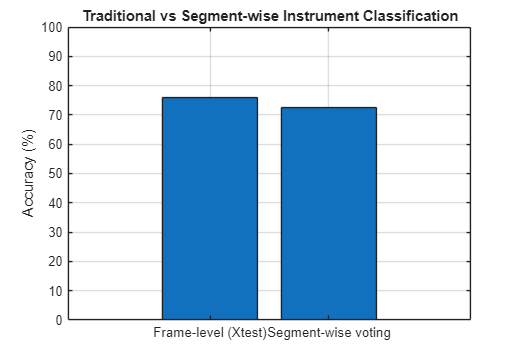


%% === 6. 可视化对比 (bar 图 + 混淆矩阵可选) ===
figure('Name','Traditional vs Segment-wise','Position',[100 100 520 360]);
bar([acc_base, acc_seg]*100);
set(gca,'XTickLabel',{'Frame-level (Xtest)','Segment-wise voting'}, 'FontSize',10);
ylabel('Accuracy (%)');
ylim([0 100]);
title('Traditional vs Segment-wise Instrument Classification');
grid on;

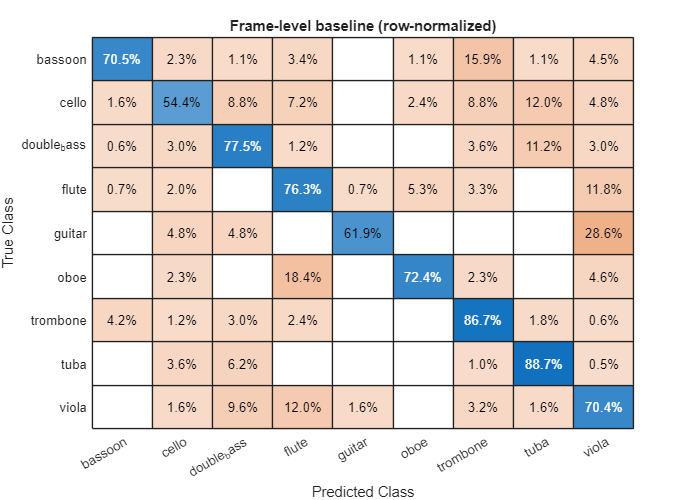


% （可选）画两个混淆矩阵，放报告里
figure('Name','Confusion – frame-level','Position',[100 100 700 500]);
confusionchart(categorical(Yte, categories(Y)), ...
               categorical(Yhat_base, categories(Y)), ...
               'Normalization','row-normalized');
title('Frame-level baseline (row-normalized)');

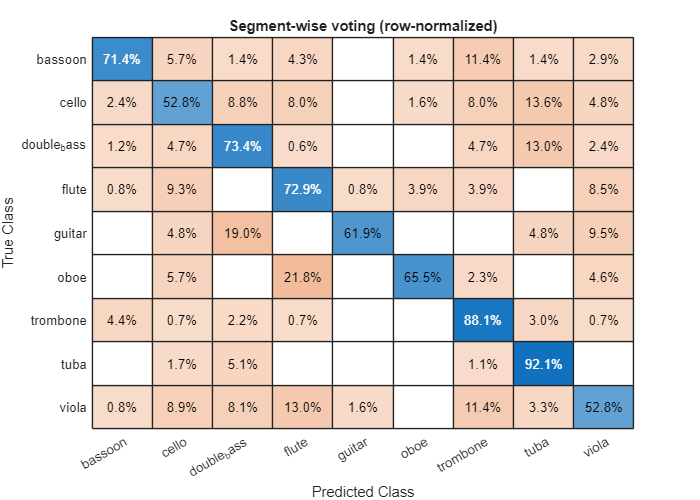


figure('Name','Confusion – segment-wise','Position',[100 100 700 500]);
confusionchart(categorical(Ytrue_seg, categories(Y)), ...
               categorical(Ypred_seg, categories(Y)), ...
               'Normalization','row-normalized');
title('Segment-wise voting (row-normalized)');


% 把 per-class P/R/F1 导出 CSV，方便直接贴表格
outDir = fullfile(projectRoot,'results','ml');
if ~isfolder(outDir), mkdir(outDir); end
writetable(tbl_base, fullfile(outDir,'perclass_frame_baseline.csv'));
writetable(tbl_seg,  fullfile(outDir,'perclass_segment_voting.csv'));

fprintf('Per-class metrics written to:\n  %s\n  %s\n', ...
    fullfile(outDir,'perclass_frame_baseline.csv'), ...
    fullfile(outDir,'perclass_segment_voting.csv'));

Per-class metrics written to:
  D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277\results\ml\perclass_frame_baseline.csv
  D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277\results\ml\perclass_segment_voting.csv



%% ==== Helper: 计算 Accuracy / Macro-F1 / Confusion / per-class metrics ====
function [acc, macroF1, C, tbl] = local_metrics(Ytrue, Ypred, classes)
    Ytrue = categorical(Ytrue, classes);
    Ypred = categorical(Ypred, classes);
    C = confusionmat(Ytrue, Ypred, 'Order', classes);

    prec = diag(C) ./ max(1, sum(C,1))';   % 按列
    rec  = diag(C) ./ max(1, sum(C,2));    % 按行
    f1   = 2*prec.*rec ./ max(1e-12, prec+rec);

    acc = mean(Ytrue == Ypred);
    macroF1 = mean(f1);

    tbl = table(classes, prec, rec, f1, ...
        'VariableNames',{'Class','Precision','Recall','F1'});
end

%% ==== Helper: 与项目一致的去静音函数 ====
function y = trim_silence_local(x, wlen, thr)
    x = x(:);
    w = hann(wlen,'periodic'); 
    hop = round(wlen/2);
    M = max(1,floor((numel(x)-wlen)/hop)+1);
    e = zeros(M,1);
    for i=1:M
        seg = x((i-1)*hop+1 : min(numel(x),(i-1)*hop+wlen));
        seg = seg .* w(1:numel(seg));
        e(i) = sum(seg.^2);
    end
    e = e ./ max(e+1e-12);
    i1 = find(e>thr,1,'first'); if isempty(i1), i1=1; end
    i2 = find(e>thr,1,'last');  if isempty(i2), i2=M; end
    s = max(1,(i1-1)*hop+1);
    t = min(numel(x),(i2-1)*hop+wlen);
    y = x(s:t);
end

%% ==== Helper: 特征提取（与训练一致：4 个谱域 + MFCC mean/std） ====
function f = extract_features_local(x, fs)
    x = x(:);

    % STFT
    wlen = round(0.04*fs); 
    hop  = round(0.02*fs); 
    nfft = 2^nextpow2(wlen);
    [S,F,~] = stft(x, fs, ...
        'Window', hann(wlen,'periodic'), ...
        'OverlapLength', wlen-hop, ...
        'FFTLength', nfft);
    mag = abs(S) + 1e-12;

    % 归一化谱
    w = mag ./ max(1e-12, sum(mag,1));
    cent = sum(w .* F, 1);
    bw   = sqrt(sum(w .* (F - cent).^2, 1));
    cent_m = mean(cent);
    bw_m   = mean(bw);

    % Rolloff (85%)
    cdf = cumsum(mag) ./ max(1e-12, sum(mag,1));
    idx = arrayfun(@(k)find(cdf(:,k)>=0.85,1,'first'), 1:size(cdf,2));
    roll = mean(F(idx));

    % ZCR
    zcr = mean(abs(diff(sign(x))))/2;

    % MFCC mean & std
    if exist('mfcc','file')
        c = mfcc(x, fs, 'LogEnergy','Ignore');   % 默认 13 维
        mf = [mean(c); std(c)]';
    else
        mf = zeros(26,1);  % 没有 Audio Toolbox 时占位
    end

    f = [cent_m, bw_m, roll, zcr, mf(:)'];
end
